# Test Case - Motor Generator 2

mdl = "MotorGenerator2_Component_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end
MotorGenerator2_Component_harness_setup

## Setup

simIn = Simulink.SimulationInput(mdl);

% Block parameters

simIn = setBlockParameter(simIn, mdl+"/Road grade", Before="-3");
simIn = setBlockParameter(simIn, mdl+"/Road grade", Time="200");
simIn = setBlockParameter(simIn, mdl+"/Road grade", After="-8");

simIn = setBlockParameter(simIn, mdl+"/Brake force", Before="0");
simIn = setBlockParameter(simIn, mdl+"/Brake force", Time="1");
simIn = setBlockParameter(simIn, mdl+"/Brake force", After="0");

simIn = setBlockParameter(simIn, mdl+"/Motor torque command", Before="-5");
simIn = setBlockParameter(simIn, mdl+"/Motor torque command", Time="300");
simIn = setBlockParameter(simIn, mdl+"/Motor torque command", After="-20");

% Initial conditions

simIn = setVariable(simIn, "initial.MG2_Temperature_degC", 20);
simIn = setVariable(simIn, "initial.MG2_AirTemp_degC", 20);
simIn = setVariable(simIn, "initial.vehicle_speed_kph", 50);

## Run Simulation

% Simulaton stop time
simIn = setModelParameter(simIn, StopTime = "500");

% Run simulation
simOut = sim(simIn);

% Copy simlog to the base workspace
% so that sscexplore can load it.
simlog = simOut.simlog;

% The use of applyToModel below is optional.
% Comment out applyToModel to avoid updating the model file,
% and you can still run simulation.
applyToModel(simIn)

## Visualize Simulation Result

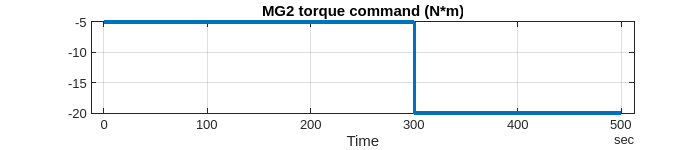

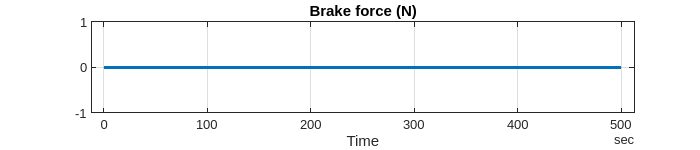

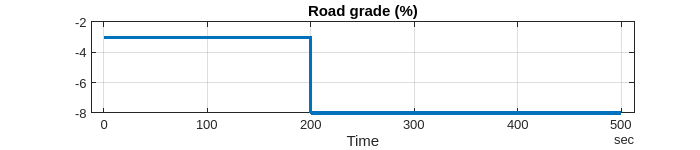

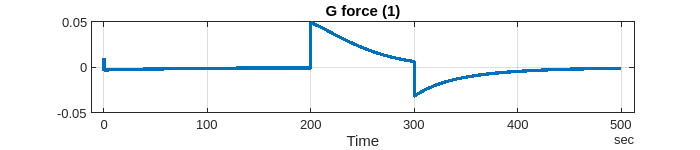

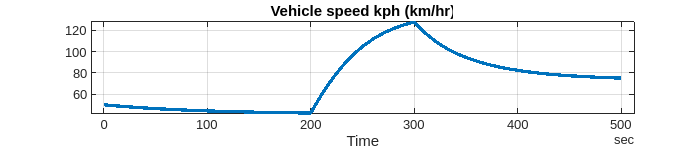

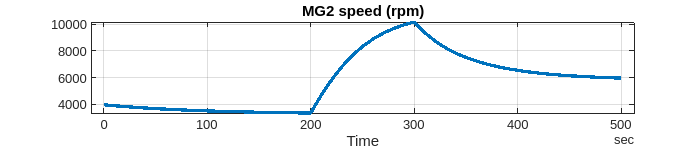

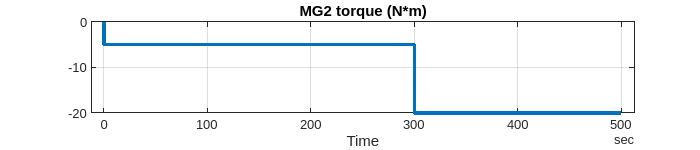

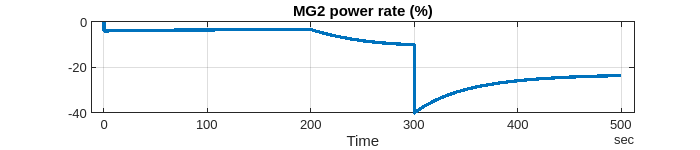

simData = extractTimetable(simOut.logsout);

sigNames = [ ...
  "MG2 torque command", ...
  "Brake force", ...
  "Road grade", ...
  "G force", ...
  "Vehicle speed kph", ...
  "MG2 speed", ...
  "MG2 torque", ...
  "MG2 power rate", ...
  "MG2 mechanical power", ...
  "MG2 temperature", ...
  "MG2 current", ...
  "MG2 voltage", ...
  "MG2 electrical power", ...
  "MG2 electrical losses", ...
  "Battery power", ...
  "Battery SOC" ];

for i = 1 : numel(sigNames)
  fig = plotSimulationResultSignal(SimData = simData, SignalName = sigNames(i));
  fig.Position(4) = 150;
end

*Copyright 2021-2022 The Mathworks, Inc.*